# Solution to *Solar Radiation II *exercise

## 1. Load data

load solar

## 2. Create plot of raw data

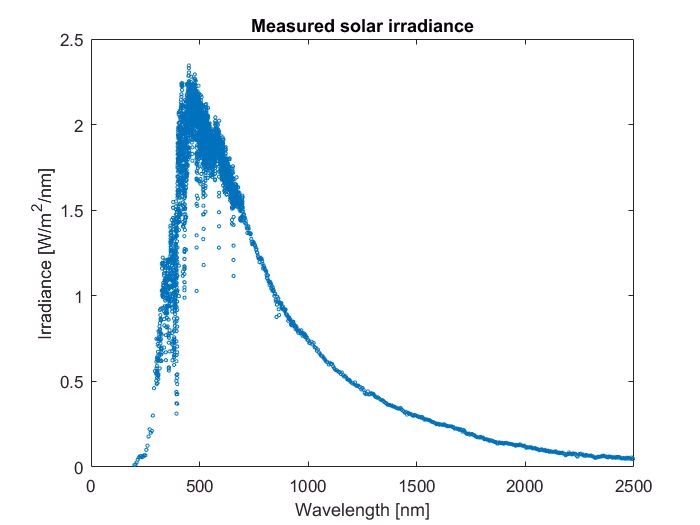

plot(lambda,irrad,'o','MarkerSize',2)
xlabel('Wavelength [nm]')
ylabel('Irradiance [W/m^2/nm]')
title('Measured solar irradiance')

## 3. Create vector

lam_th = 200:2500;

## 4. Calculate spectrum

alpha = 9.9214e15;
beta = 2604.1;
I_th = alpha./(lam_th.^5.*(exp(beta./lam_th)-1));

## 5. Create second plot with theorectical curve

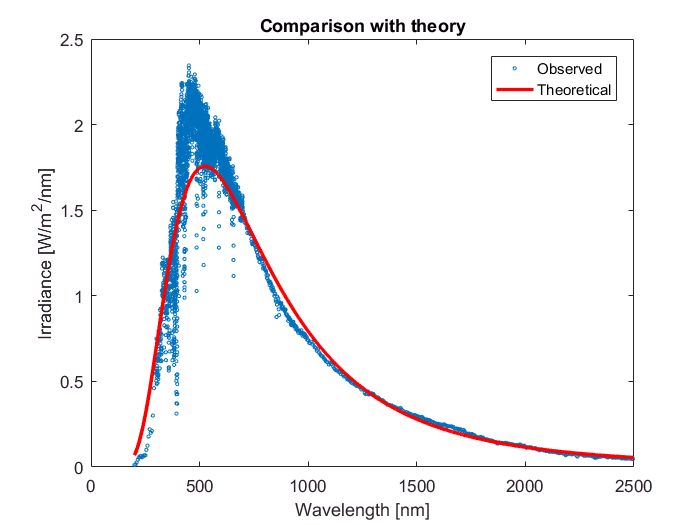

plot(lambda,irrad,'o','MarkerSize',2)
hold on
plot(lam_th,I_th,'r','LineWidth',2)
hold off
xlabel('Wavelength [nm]')
ylabel('Irradiance [W/m^2/nm]')
title('Comparison with theory')
legend('Observed','Theoretical')

## 6. Determine solar constant

SolConst = sum(I_th);
disp(['Solar constant is ',num2str(SolConst/1000),' kW/m^2'])

Solar constant is 1.3459 kW/m^2
